## **Description of the daily puzzle:**

**Tailing Pentomino Puzzle of Daily Calender**

* Test in Matlab R2021b, with Ghostscript 9.54.0 (https://github.com/ArtifexSoftware/ghostpdl-downloads/releases)

clear

time=clock;
seed=round(sum(time(4:6))*sum(time(2:3))/10);
rng(seed);

%% Frame shape
FrameDefault = false(15,15);
FrameDefault([1,2,14,15],[1,15]) = true;
FrameDefault([1,15],[2,14]) = true;

Text_Frame = {'','Jan','Feb','Mar','Apr','May',''; 'Jun','Jul','Aug','Sep','Oct','Nov','Dec';
        '','','','','','','';'','1','2','3','4','5','';
        '6','7','8','9','10','11','12';'13','14','15','16','17','18','19';
        '20','21','22','23','24','25','26';'','27','28','29','30','31','';
        '','','','','','','';'Mon','Tue','Wed','Thu','Fri','Sat','Sun';'Mon','Tue','Wed','Thu','Fri','Sat','Sun';};

if false
    figure;
    temp_FrameDefault = [flip(~FrameDefault), ones(size(FrameDefault,1),1); ones(1,size(FrameDefault,2)+1)];
    H1 = pcolor(temp_FrameDefault);
    colormap(gray(2));
    xlim([1 16])
    ylim([1 16])
    axis equal
    axis off
    set(gca, 'xticklabel', [], 'yticklabel', [], 'FontName', 'Courier')
    set(gcf,'Position',[0 0 3000 3000]);
    labelTable(FrameDefault, Text_Frame);
end


%% Pieces shape
% 1 pieces, start in a 7x7 empty space
% 34 pieces, start in a 5x5 empty space
NoPuzzlePieces = 35;
NoExtra = 1;
PuzzlePieces = repmat({false(5,5)},NoPuzzlePieces,8);
for i=1:NoExtra
    for j=1:8
        PuzzlePieces{i,j} = false(7,7);
    end
end
PuzzlePiecesBlockNo = zeros(NoPuzzlePieces,1);

% □□□□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□
% □□□□□□□ % □□■□□ % ■□□■□ % □■■□□ % ■□□□□ % □■□□□ % □■□■□
% ■■■■■■□ % ■■■■■ % ■■■■□ % ■■■■□ % ■■■■□ % ■■■■□ % □■■■□
% □□□□□□□ % □□□□□ % □□□□□ % □□□□□ % ■□□□□ % □■□□□ % □□■□□
% □□□□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□

PuzzlePieces{1,1}(4,1:6)=true;
PuzzlePieces{3,1}(3,1:5)=true;PuzzlePieces{3,1}(2,3)=true;
PuzzlePieces{4,1}(3,1:4)=true;PuzzlePieces{4,1}(2,[1,4])=true;
PuzzlePieces{5,1}(3,1:4)=true;PuzzlePieces{5,1}(2,2:3)=true;
PuzzlePieces{6,1}(3,1:4)=true;PuzzlePieces{6,1}(2:4,1)=true;
PuzzlePieces{7,1}(3,1:4)=true;PuzzlePieces{7,1}(2:4,2)=true;
PuzzlePieces{8,1}(3,2:4)=true;PuzzlePieces{8,1}(2,[2,4])=true;PuzzlePieces{8,1}(4,3)=true;

% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□
% □■■■□ % □□■■■ % □■■■□ % □□□■□ % □□■□□ % □□■■□ % □■□□□
% □■■■□ % ■■■□□ % ■■■□□ % ■■■■□ % ■■■■□ % □■■□□ % □■■□□
% □□□□□ % □□□□□ % □□□□□ % ■□□□□ % □■□□□ % ■■□□□ % □■■■□
% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□

PuzzlePieces{2,1}(2,2:4)=true;PuzzlePieces{2,1}(3,2:4)=true;
PuzzlePieces{9,1}(2,3:5)=true;PuzzlePieces{9,1}(3,1:3)=true;
PuzzlePieces{10,1}(2,2:4)=true;PuzzlePieces{10,1}(3,1:3)=true;
PuzzlePieces{11,1}(3,1:4)=true;PuzzlePieces{11,1}(2,4)=true;PuzzlePieces{11,1}(4,1)=true;
PuzzlePieces{12,1}(3,1:4)=true;PuzzlePieces{12,1}(2,3)=true;PuzzlePieces{12,1}(4,2)=true;
PuzzlePieces{13,1}(2,3:4)=true;PuzzlePieces{13,1}(3,2:3)=true;PuzzlePieces{13,1}(4,1:2)=true;
PuzzlePieces{14,1}(2,2)=true;PuzzlePieces{14,1}(3,2:3)=true;PuzzlePieces{14,1}(4,2:4)=true;

% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□■□
% □□■□□ % □□□□■ % □□□■□ % □□□■■ % □□■■□ % □■□■□ % □□□■□
% □■■■□ % ■■■■■ % ■■■■■ % ■■■■□ % ■■■■□ % ■■■■□ % ■■■■□
% □■■□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□
% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□

PuzzlePieces{15,1}(2,3)=true;PuzzlePieces{15,1}(3,2:4)=true;PuzzlePieces{15,1}(4,2:3)=true;
PuzzlePieces{16,1}(3,1:5)=true;PuzzlePieces{16,1}(2,5)=true;
PuzzlePieces{17,1}(3,1:5)=true;PuzzlePieces{17,1}(2,4)=true;
PuzzlePieces{18,1}(3,1:4)=true;PuzzlePieces{18,1}(2,4:5)=true;
PuzzlePieces{19,1}(3,1:4)=true;PuzzlePieces{19,1}(2,3:4)=true;
PuzzlePieces{20,1}(3,1:4)=true;PuzzlePieces{20,1}(2,[2,4])=true;
PuzzlePieces{21,1}(3,1:4)=true;PuzzlePieces{21,1}(1:2,4)=true;

% □□■□□ % □□□□□ % □□□□□ % □□■□□ % □□□□□ % □□□■□ % □□□□□
% □□■□□ % □□■□□ % □■□□□ % □■■■□ % □■□■■ % □■■■□ % □■■■□
% ■■■■□ % ■■■■□ % ■■■■□ % □■□□□ % □■■■□ % □□■□□ % □□■■□
% □□□□□ % □□□■□ % □□□■□ % □■□□□ % □□□□□ % □□■□□ % □□■□□
% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□

PuzzlePieces{22,1}(3,1:4)=true;PuzzlePieces{22,1}(1:2,3)=true;
PuzzlePieces{23,1}(3,1:4)=true;PuzzlePieces{23,1}(2,3)=true;PuzzlePieces{23,1}(4,4)=true;
PuzzlePieces{24,1}(3,1:4)=true;PuzzlePieces{24,1}(2,2)=true;PuzzlePieces{24,1}(4,4)=true;
PuzzlePieces{25,1}(2,2:4)=true;PuzzlePieces{25,1}(1,3)=true;PuzzlePieces{25,1}(3:4,2)=true;
PuzzlePieces{26,1}(3,2:4)=true;PuzzlePieces{26,1}(2,[2,4,5])=true;
PuzzlePieces{27,1}(2,2:4)=true;PuzzlePieces{27,1}(1,4)=true;PuzzlePieces{27,1}(3:4,3)=true;
PuzzlePieces{28,1}(2,2:4)=true;PuzzlePieces{28,1}(3,3:4)=true;PuzzlePieces{28,1}(4,3)=true;

% □□□■□ % □□□■□ % □□■■□ % □□□□□ % □□□□□ % □□■■□ % □□□□□
% □□■■□ % □■■■□ % □■■□□ % □■■■□ % □■□■□ % □□■□□ % □□□■□
% □■■□□ % □■□□□ % □■□□□ % □■□■□ % □■■■□ % □■■□□ % □■■■□
% □□■□□ % □■□□□ % □■□□□ % □■□□□ % □■□□□ % □■□□□ % □■■□□
% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□

PuzzlePieces{29,1}(3,2)=true;PuzzlePieces{29,1}(2:4,3)=true;PuzzlePieces{29,1}(1:2,4)=true;
PuzzlePieces{30,1}(1,4)=true;PuzzlePieces{30,1}(2,2:4)=true;PuzzlePieces{30,1}(3:4,2)=true;
PuzzlePieces{31,1}(1,3:4)=true;PuzzlePieces{31,1}(2,2:3)=true;PuzzlePieces{31,1}(3:4,2)=true;
PuzzlePieces{32,1}(2,2:4)=true;PuzzlePieces{32,1}(3:4,2)=true;PuzzlePieces{32,1}(3,4)=true;
PuzzlePieces{33,1}(2:4,2)=true;PuzzlePieces{33,1}(3,3)=true;PuzzlePieces{33,1}(2:3,4)=true;
PuzzlePieces{34,1}(3:4,2)=true;PuzzlePieces{34,1}(1:3,3)=true;PuzzlePieces{34,1}(1,4)=true;
PuzzlePieces{35,1}(2,4)=true;PuzzlePieces{35,1}(3,2:4)=true;PuzzlePieces{35,1}(4,2:3)=true;

for n=1:NoPuzzlePieces
    PuzzlePiecesBlockNo(n) = sum(PuzzlePieces{n,1},'all');
end

if false
    MaxNperRow = 7;
    NRow = ceil(NoPuzzlePieces/MaxNperRow);
    H2 = tiledlayout(NRow,MaxNperRow,'TileSpacing','compact','Padding','loose');
    for i=1:NoExtra
        nexttile
        H20 = pcolor([PuzzlePieces{i,1},zeros(7,1);zeros(1,8)]);
        colormap([1 1 1; 0 0 0]);
        axis equal
        xlim([1 8])
        ylim([1 8])
        set(gca, 'xticklabel', [], 'yticklabel', []);
    end
    for i=NoExtra+1:NoPuzzlePieces
        nexttile
        H20 = pcolor([PuzzlePieces{i,1},zeros(5,1);zeros(1,6)]);
        colormap([1 1 1; 0 0 0]);
        axis equal
        xlim([1 6])
        ylim([1 6])
        set(gca, 'xticklabel', [], 'yticklabel', []);
    end
end

## **Choose the Date:**

% Flip Vertical, Flip Horizontal, Roate(counterclockwise) 90
% [Boolean number, Boolean number, Boolean number]
for n=1:NoPuzzlePieces
    for i=0:1:7
        temp_p = PuzzlePieces{n,1};
        binstr = dec2bin(i,3)=='1';
        if binstr(3)
            temp_p = flip(temp_p);
        end
        if binstr(2)
            temp_p = flip(temp_p,2);
        end
        if binstr(1)
            temp_p = rot90(temp_p);
        end
        PuzzlePieces{n,i+1} = temp_p;
    end
end

%% Initalization
SizeFrame = size(FrameDefault);
LN = SizeFrame(1)*SizeFrame(2)*8;
ExpandedPuzzlePieces = repmat({false(SizeFrame(1),SizeFrame(2))},NoPuzzlePieces,LN);
ExpandedPuzzlePiecesFlag = false(NoPuzzlePieces,LN);
% 5x5 pieces
ExpandedFrame = true(SizeFrame(1)+4, SizeFrame(2)+4);
ExpandedFrame(3:SizeFrame(1)+2,3:SizeFrame(2)+2) = FrameDefault;
for i=NoExtra+1:NoPuzzlePieces
    for L0=1:LN
        R0 = ceil(L0/8);
        P0 = rem(L0,8);
        if P0==0
            P0 = 8;
        end
        R0x = ceil(R0/SizeFrame(2));
        R0y = rem(R0,SizeFrame(2));
        if R0y==0
            R0y = SizeFrame(2);
        end
        tempFrame = false(SizeFrame(1)+4, SizeFrame(2)+4);
        tempFrame(R0x:R0x+4,R0y:R0y+4) = PuzzlePieces{i,P0};
        OverlayFrame = tempFrame & ExpandedFrame;
        if sum(OverlayFrame,'all')==0
            ExpandedPuzzlePieces{i,L0} = tempFrame(3:SizeFrame(1)+2,3:SizeFrame(2)+2);
            ExpandedPuzzlePiecesFlag(i,L0) = true;
        end
    end
end
% 7x7 pieces
ExpandedFrame = true(SizeFrame(1)+6, SizeFrame(2)+6);
ExpandedFrame(4:SizeFrame(1)+3,4:SizeFrame(2)+3) = FrameDefault;
for i=1:NoExtra
    for L0=1:LN
        R0 = ceil(L0/8);
        P0 = rem(L0,8);
        if P0==0
            P0 = 8;
        end
        R0x = ceil(R0/SizeFrame(2));
        R0y = rem(R0,SizeFrame(2));
        if R0y==0
            R0y = SizeFrame(2);
        end
        tempFrame = false(SizeFrame(1)+6, SizeFrame(2)+6);
        tempFrame(R0x:R0x+6,R0y:R0y+6) = PuzzlePieces{i,P0};
        OverlayFrame = tempFrame & ExpandedFrame;
        if sum(OverlayFrame,'all')==0
            ExpandedPuzzlePieces{i,L0} = tempFrame(4:SizeFrame(1)+3,4:SizeFrame(2)+3);
            ExpandedPuzzlePiecesFlag(i,L0) = true;
        end
    end
end

%Remove duplicates
for i=NoPuzzlePieces:NoPuzzlePieces
    tempIndex = zeros(LN,SizeFrame(1),'int64');
    for L0=1:LN
        reshapeMatrix = ExpandedPuzzlePieces{i,L0};
        for j=1:SizeFrame(1)
            % treat matrix of [0,1] as binary
            binValue = num2str(reshapeMatrix(j,:),'%d');
            tempIndex(L0,j) = LongBin2Dec(binValue);
        end
    end
    [~, UniqueIndex, ~] = unique(tempIndex,'rows');
    tempFlag = false(1,LN);
    tempFlag(UniqueIndex) = true;
    ExpandedPuzzlePiecesFlag(i,:) = ExpandedPuzzlePiecesFlag(i,:) & tempFlag;
end

% Randomization
ExpandedPuzzlePieces_temp = ExpandedPuzzlePieces;
ExpandedPuzzlePiecesFlag_temp = ExpandedPuzzlePiecesFlag;
for i=1:NoPuzzlePieces
    newIndx = randperm(LN);
    for j=1:LN
        ExpandedPuzzlePieces{i,j} = ExpandedPuzzlePieces_temp{i,newIndx(j)};
        ExpandedPuzzlePiecesFlag(i,j) = ExpandedPuzzlePiecesFlag_temp(i,newIndx(j));
    end
end
clear ExpandedPuzzlePieces_temp ExpandedPuzzlePiecesFlag_temp

NoBlocks = SizeFrame(1)*SizeFrame(2);
MaxIndex = sum(ExpandedPuzzlePiecesFlag,'all') + 1;
ExactCoverMatrix1 = false(MaxIndex, NoBlocks + NoPuzzlePieces + 1);
% raw: all possible positions of the puzzle pieces; FrameQuestion
% column: each block of the puzzle is filled; each piece is chosen; Question is solved

% Each possible positions of the puzzle pieces
IndexofPuzzlePieces = cell(1,sum(ExpandedPuzzlePiecesFlag,'all'));
Index_temp = 0;
for i=1:NoPuzzlePieces
    for j=1:LN
        if ExpandedPuzzlePiecesFlag(i,j)
            Index_temp = Index_temp+1;
            IndexofPuzzlePieces{Index_temp} = [i,j];
            ExactCoverMatrix1(Index_temp,1:NoBlocks) = reshape(ExpandedPuzzlePieces{i,j}, 1, NoBlocks);
            ExactCoverMatrix1(Index_temp,NoBlocks+i) = true;
        end
    end
end

%% Qusetion
Year = "2025";
Month = 9;
Day = 5;
Week = 5;
Year = int32(str2num(Year));
if ~isempty(Year)
    [DayNumber,~] = weekday([num2str(Month,'%02d'),'/',num2str(Day,'%02d'),'/',num2str(Year,'%04d')]);
    if DayNumber==1
        Week = 7;
    else
        Week = DayNumber-1;
    end
end
Week2String = ['Mon';'Tue';'Wed';'Thu';'Fri';'Sat';'Sun'];
FrameQuestion1 = dailyPuzzle_Hexominoes(Month,Day,Week,0);
FrameQuestion2 = dailyPuzzle_Hexominoes(Month,Day,Week,1);
filename = ['output/Result_', date2String(Month,Day), '(', Week2String(Week,:), ')','.txt'];
if ~isfolder('output')
    mkdir('output');
end

Frame1 = FrameDefault | FrameQuestion1;
Frame2 = FrameDefault | FrameQuestion2;

IsOutput = false;

* Install Ghostscript (https://www.ghostscript.com/releases/gsdnld.html) if you want to merge pdf files.

fprintf(['Solving the puzzle on ', date2String(Month,Day), ' (', Week2String(Week,:), ')', ', it might take a while.\n']);

Solving the puzzle on Sep-05th (Fri), it might take a while.


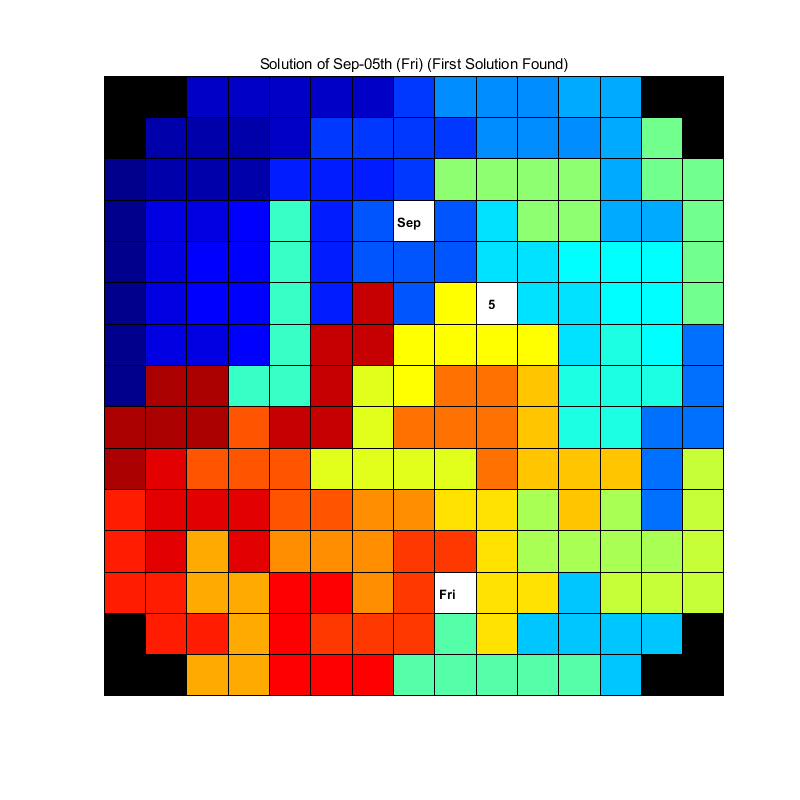

Done.



Solution_one = [];

NoBlocks = SizeFrame(1)*SizeFrame(2);
MaxIndex = sum(ExpandedPuzzlePiecesFlag,'all') + 1;
ExactCoverMatrix1 = false(MaxIndex, NoBlocks + NoPuzzlePieces + 1);
% raw: all possible positions of the puzzle pieces; FrameQuestion
% column: each block of the puzzle is filled; each piece is chosen; Question is solved

% FrameQuestion
ExactCoverMatrix1(end,:) = [reshape(Frame1, 1, NoBlocks), false(1,NoPuzzlePieces), true];
% Each possible positions of the puzzle pieces
IndexofPuzzlePieces = cell(1,sum(ExpandedPuzzlePiecesFlag,'all'));
Index_temp = 0;
for i=1:NoPuzzlePieces
    for j=1:LN
        if ExpandedPuzzlePiecesFlag(i,j)
            Index_temp = Index_temp+1;
            IndexofPuzzlePieces{Index_temp} = [i,j];
            ExactCoverMatrix1(Index_temp,1:NoBlocks) = reshape(ExpandedPuzzlePieces{i,j}, 1, NoBlocks);
            ExactCoverMatrix1(Index_temp,NoBlocks+i) = true;
        end
    end
end
ExactCoverMatrix2 = ExactCoverMatrix1;
ExactCoverMatrix2(end,:) = [reshape(Frame2, 1, NoBlocks), false(1,NoPuzzlePieces), true];

tic
[Sol1, timeout1] = AlgorithmXexcov(ExactCoverMatrix1',[1:MaxIndex],10);

if timeout1 || isempty(Sol1)
    tic
    [Sol2, timeout2] = AlgorithmXexcov(ExactCoverMatrix2',[1:MaxIndex],10);
    if timeout2 || isempty(Sol2)
        if timeout1
            tic
            [Sol1, timeout1] = AlgorithmXexcov(ExactCoverMatrix1',[1:MaxIndex],200);
            if timeout1 || isempty(Sol1)
                tic
                [Sol2, timeout2] = AlgorithmXexcov(ExactCoverMatrix2',[1:MaxIndex],200);
                if ~timeout2 && ~isempty(Sol2)
                    Solution_one = Sol2{1};
                end
            else
                Solution_one = Sol1{1};
            end
        end
    else
        Solution_one = Sol2{1};
    end
else
    Solution_one = Sol1{1};
end

if timeout1 && timeout2
    fprintf(['Time out!\n']);
end

Solution_output = zeros(1,NoPuzzlePieces);
if ~isempty(Solution_one)
    for i=1:length(Solution_one)
        if Solution_one(i)<MaxIndex
            Index = IndexofPuzzlePieces{Solution_one(i)};
            Solution_output(1,Index(1)) = Index(2);
        end
    end
end

%% Output
ColorMaps = [1 1 1; jet(NoPuzzlePieces); 0 0 0];
if ~isempty(Solution_one)
    HeatMapMatrix = zeros(SizeFrame(1), SizeFrame(2));
    for n=1:NoPuzzlePieces
        HeatMapMatrix = HeatMapMatrix + n.*ExpandedPuzzlePieces{n,Solution_output(n)};
    end
    HeatMapMatrix = HeatMapMatrix + (NoPuzzlePieces+1).*FrameDefault;
    temp_HeatMapMatrix = [flip(HeatMapMatrix), zeros(size(HeatMapMatrix,1),1); zeros(1,size(HeatMapMatrix,2)+1)];
    figure;
    H0 = pcolor(temp_HeatMapMatrix);
    colormap(ColorMaps);
    axis equal
    xlim([1 16])
    ylim([1 16])
    set(gca, 'xticklabel', [], 'yticklabel', [])
    set(gcf,'Position',[0 0 3000 3000])
    labelTable(HeatMapMatrix, Text_Frame)
    titlename = ['Solution of ', date2String(Month,Day), ' (', Week2String(Week,:), ') (First Solution Found)'];
    title(titlename);
    if IsOutput
        PrintFileName = ['output/Solution_', date2String(Month,Day), '(', Week2String(Week,:), ')_FirstSolFound.pdf'];
        print(gcf,PrintFileName,'-dpdf','-bestfit'); %PDf
    end
    fprintf('Done.\n');
else
    fprintf('No solution was found for Daily Puzzle on %s.\n', date2String(Month,Day));
end


 
%% Function

function [frame_question] = dailyPuzzle_Hexominoes(Month,Day,Week,offset)
    frame_question = false(15,15);
    MN = [3,6; 3,7; 3,8; 3,9; 3,10; 4,5; 4,6; 4,7; 4,8; 4,9; 4,10; 4,11];
    frame_question(MN(Month,1),MN(Month,2)) = true;
    DN = [6,6; 6,7; 6,8; 6,9; 6,10; 7,5; 7,6; 7,7; 7,8; 7,9; 7,10; 7,11; 8,5; 8,6; 8,7; 8,8; 8,9; 8,10; 8,11; 9,5; 9,6; 9,7; 9,8; 9,9; 9,10; 9,11; 10,6; 10,7; 10,8; 10,9; 10,10];
    frame_question(DN(Day,1),DN(Day,2)) = true;
    frame_question(12+offset,4+Week) = true;
end

function [Dec] = LongBin2Dec(Bin)
    MaxLen = 52;
    BinLen = length(Bin);
    n = ceil(BinLen ./ MaxLen);
    Dec = zeros(1,'int64');
    for i = 1:n
        BinPart = Bin((i - 1) * MaxLen + 1:min(i * MaxLen, BinLen));
        Dec = Dec .* 2^length(BinPart) + bin2dec(BinPart);
    end
end

function [] = labelTable(Frame, TextFrame)
    Frame = Frame(3:13,5:11);
    row = size(Frame,1);
    column = size(Frame,2);
    for i=1:row
        for j=1:column
            if Frame(i,j)==0
                shiftx = 0.3+0.1*(2-length(TextFrame{i,j}));
                text(j+shiftx+3.9, row+1.5-i+2, TextFrame{i,j}, 'FontWeight', 'bold');
            end
        end
    end
end

function [StringDate] = date2String(Month, Day)
    switch Month
        case 1
            StringDate1 = 'Jan';
        case 2
            StringDate1 = 'Feb';
        case 3
            StringDate1 = 'Mar';
        case 4
            StringDate1 = 'Apr';
        case 5
            StringDate1 = 'May';
        case 6
            StringDate1 = 'Jun';
        case 7
            StringDate1 = 'Jul';
        case 8
            StringDate1 = 'Aug';
        case 9
            StringDate1 = 'Sep';
        case 10
            StringDate1 = 'Oct';
        case 11
            StringDate1 = 'Nov';
        case 12
            StringDate1 = 'Dec';
    end
    switch Day
        case 1
            StringDate2 = '01st';
        case 2
            StringDate2 = '02nd';
        case 3
            StringDate2 = '03rd';
        case 21
            StringDate2 = '21st';
        case 22
            StringDate2 = '22nd';
        case 23
            StringDate2 = '23rd';
        case 31
            StringDate2 = '31st';
        otherwise
            StringDate2 = [num2str(Day,'%02d'), 'th'];
    end
    StringDate = [StringDate1, '-', StringDate2];
end

%% https://www.mathworks.com/matlabcentral/cody/problems/56588-exact-cover/solutions
%% Problem 56588. Exact Cover, Solution 10165687
%% Submitted on 17 Dec 2022 by Tim
%% Knuth's Algorithm X (utilizing the Dancing Links technique)


function [S, timeout]=AlgorithmXexcov(Q,L,tout)
% Q: [MxN logic matrix] the cover matrix, M is the universe, N is the sets with which to try to exactly cover the respective universe 
% L: [1:N]
% return when find >=1 solution(s)
S={};
timeout = false;
[~,i]=min(sum(Q,2));
for j=find(Q(i,:))
   if all(Q(:,j))
      S=[S L(j)];
   else
      J=~any(Q(Q(:,j),:),1);
      [T,~]=AlgorithmXexcov(Q(~Q(:,j),J),L(J),tout);
      for m=1:numel(T)
          S=[S [L(j) T{m}]];
      end
   end
   if ~isempty(S)
       return
   end
   elapsed_time = toc;
   if elapsed_time > tout
       timeout = true;
       S={};
       return
   end
end
end

%APPEND_PDFS Appends/concatenates multiple PDF files
%
% Example:
%   append_pdfs(output, input1, input2, ...)
%   append_pdfs(output, input_list{:})
%   append_pdfs test.pdf temp1.pdf temp2.pdf
%
% This function appends multiple PDF files to an existing PDF file, or
% concatenates them into a PDF file if the output file doesn't yet exist.
%
% This function requires that you have ghostscript installed on your
% system. Ghostscript can be downloaded from: http://www.ghostscript.com
%
% IN:
%    output - string of output file name (including the extension, .pdf).
%             If it exists it is appended to; if not, it is created.
%    input1 - string of an input file name (including the extension, .pdf).
%             All input files are appended in order.
%    input_list - cell array list of input file name strings. All input
%                 files are appended in order.

% Copyright: Oliver Woodford, 2011

% Thanks to Reinhard Knoll for pointing out that appending multiple pdfs in
% one go is much faster than appending them one at a time.

% Thanks to Michael Teo for reporting the issue of a too long command line.
% Issue resolved on 5/5/2011, by passing gs a command file.

% Thanks to Martin Wittmann for pointing out the quality issue when
% appending multiple bitmaps.
% Issue resolved (to best of my ability) 1/6/2011, using the prepress
% setting

% modified
function append_pdfs_edit(varargin)
% Are we appending or creating a new file
varargin = varargin{1};
append = exist(varargin{1}, 'file') == 2;
if append
    output = [tempname '.pdf'];
else
    output = varargin{1};
    varargin = varargin(2:end);
end
% Create the command file
cmdfile = [tempname '.txt'];
fh = fopen(cmdfile, 'w');
fprintf(fh, '-q -dNOPAUSE -dBATCH -sDEVICE=pdfwrite -dPDFSETTINGS=/prepress -sOutputFile="%s" -f', output);
fprintf(fh, ' "%s"', varargin{:});
fclose(fh);
% Call ghostscript
ghostscript(['@"' cmdfile '"']);
% Delete the command file
delete(cmdfile);
% Rename the file if needed
if append
    movefile(output, varargin{1});
end
end

function varargout = ghostscript(cmd)
%GHOSTSCRIPT  Calls a local GhostScript executable with the input command
%
% Example:
%   [status result] = ghostscript(cmd)
%
% Attempts to locate a ghostscript executable, finally asking the user to
% specify the directory ghostcript was installed into. The resulting path
% is stored for future reference.
% 
% Once found, the executable is called with the input command string.
%
% This function requires that you have Ghostscript installed on your
% system. You can download this from: http://www.ghostscript.com
%
% IN:
%   cmd - Command string to be passed into ghostscript.
%
% OUT:
%   status - 0 iff command ran without problem.
%   result - Output from ghostscript.

% Copyright: Oliver Woodford, 2009-2010

% Thanks to Jonas Dorn for the fix for the title of the uigetdir window on
% Mac OS.

% Thanks to Nathan Childress for the fix to the default location on 64-bit
% Windows systems.

% 27/4/11 - Find 64-bit Ghostscript on Windows. Thanks to Paul Durack and
% Shaun Kline for pointing out the issue

% 4/5/11 - Thanks to David Chorlian for pointing out an alternative
% location for gs on linux.

% Call ghostscript
[varargout{1:nargout}] = system(sprintf('"%s" %s', gs_path, cmd));
return
end

function path = gs_path
% Return a valid path
% Start with the currently set path
path = user_string('ghostscript');
% Check the path works
if check_gs_path(path)
    return
end
% Check whether the binary is on the path
if ispc
    bin = {'gswin32c.exe', 'gswin64c.exe'};
else
    bin = {'gs'};
end
for a = 1:numel(bin)
    path = bin{a};
    if check_store_gs_path(path)
        return
    end
end
% Search the obvious places
if ispc
    default_location = 'C:\Program Files\gs\';
    dir_list = dir(default_location);
    if isempty(dir_list)
        default_location = 'C:\Program Files (x86)\gs\'; % Possible location on 64-bit systems 
        dir_list = dir(default_location);
    end
    executable = {'\bin\gswin32c.exe', '\bin\gswin64c.exe'};
    ver_num = 0;
    % If there are multiple versions, use the newest
    for a = 1:numel(dir_list)
        ver_num2 = sscanf(dir_list(a).name, 'gs%g');
        if ~isempty(ver_num2) && ver_num2 > ver_num
            for b = 1:numel(executable)
                path2 = [default_location dir_list(a).name executable{b}];
                if exist(path2, 'file') == 2
                    path = path2;
                    ver_num = ver_num2;
                end
            end
        end
    end
    if check_store_gs_path(path)
        return
    end
else
    bin = {'/usr/bin/gs', '/usr/local/bin/gs'};
    for a = 1:numel(bin)
        path = bin{a};
        if check_store_gs_path(path)
            return
        end
    end
end
% Ask the user to enter the path
while 1
    if strncmp(computer, 'MAC', 3) % Is a Mac
        % Give separate warning as the uigetdir dialogue box doesn't have a
        % title
        uiwait(warndlg('Ghostscript not found. Please locate the program.'))
    end
    base = uigetdir('/', 'Ghostcript not found. Please locate the program.');
    if isequal(base, 0)
        % User hit cancel or closed window
        break;
    end
    base = [base filesep];
    bin_dir = {'', ['bin' filesep], ['lib' filesep]};
    for a = 1:numel(bin_dir)
        for b = 1:numel(bin)
            path = [base bin_dir{a} bin{b}];
            if exist(path, 'file') == 2
                if check_store_gs_path(path)
                    return
                end
            end
        end
    end
end
error('Ghostscript not found. Have you installed it from www.ghostscript.com?');
end

function good = check_store_gs_path(path)
% Check the path is valid
good = check_gs_path(path);
if ~good
    return
end
% Update the current default path to the path found
if ~user_string('ghostscript', path)
    warning('Path to ghostscript installation could not be saved. Enter it manually in ghostscript.txt.');
    return
end
return
end

function good = check_gs_path(path)
% Check the path is valid
[good message] = system(sprintf('"%s" -h', path));
good = good == 0;
return
end

%USER_STRING  Get/set a user specific string
%
% Examples:
%   string = user_string(string_name)
%   saved = user_string(string_name, new_string)
%
% Function to get and set a string in a system or user specific file. This
% enables, for example, system specific paths to binaries to be saved.
%
% IN:
%   string_name - String containing the name of the string required. The
%                 string is extracted from a file called (string_name).txt,
%                 stored in the same directory as user_string.m.
%   new_string - The new string to be saved under the name given by
%                string_name.
%
% OUT:
%   string - The currently saved string. Default: ''.
%   saved - Boolean indicating whether the save was succesful

% Copyright (C) Oliver Woodford 2011

% This method of saving paths avoids changing .m files which might be in a
% version control system. Instead it saves the user dependent paths in
% separate files with a .txt extension, which need not be checked in to
% the version control system. Thank you to Jonas Dorn for suggesting this
% approach.

function string = user_string(string_name, string)
if ~ischar(string_name)
    error('string_name must be a string.');
end
% Create the full filename
string_name = fullfile(fileparts(mfilename('fullpath')), '.ignore', [string_name '.txt']);
if nargin > 1
    % Set string
    if ~ischar(string)
        error('new_string must be a string.');
    end
    % Make sure the save directory exists
    dname = fileparts(string_name);
    if ~exist(dname, 'dir')
        % Create the directory
        try
            if ~mkdir(dname)                
                string = false;
                return
            end
        catch
            string = false;
            return
        end
        % Make it hidden
        try
            fileattrib(dname, '+h');
        catch
        end
    end
    % Write the file
    fid = fopen(string_name, 'w');
    if fid == -1
        string = false;
        return
    end
    try
        fwrite(fid, string, '*char');
    catch
        fclose(fid);
        string = false;
        return
    end
    fclose(fid);
    string = true;
else
    % Get string
    fid = fopen(string_name, 'r');
    if fid == -1
        string = '';
        return
    end
    string = fread(fid, '*char')';
    fclose(fid);
end
return
end